# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 16-May-2020 17:55:09

## Carregar les dades

trainData = datastore("..\input\RebeloDataset\Dataset", "IncludeSubfolders",true, "LabelSource","foldernames");

[trainData, valiData] = splitEachLabel(trainData, 0.7);

trainData = transform(trainData, @binarizeValidation, "IncludeInfo", true);
valiData = transform(valiData, @binarizeValidation, "IncludeInfo", true);

read(valiData)

ans = 1×2 cell array
    {20×20 logical}    {[0]}


## Create the Array of Layers

layers = [
    imageInputLayer([20 20 1],"Name","imageinput")
    fullyConnectedLayer(1024, "Name", "FirstLayer")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    fullyConnectedLayer(512, "Name", "SecondLayer")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    fullyConnectedLayer(length(unique(trainData.UnderlyingDatastore.Labels)),"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Plot the Layers

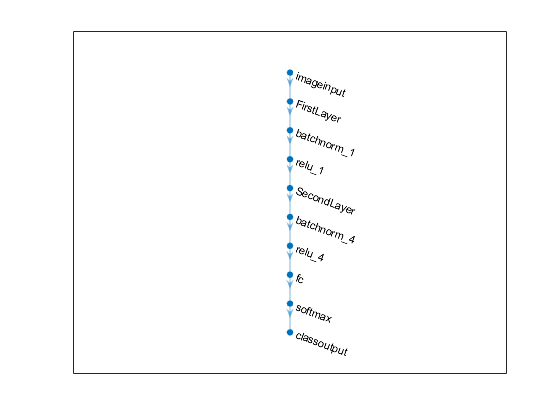

plot(layerGraph(layers));

## Opcions de training

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData', valiData, ...
    'ValidationFrequency',30, ...
    'Verbose',true, ...
    'Plots','training-progress');

## Entrena

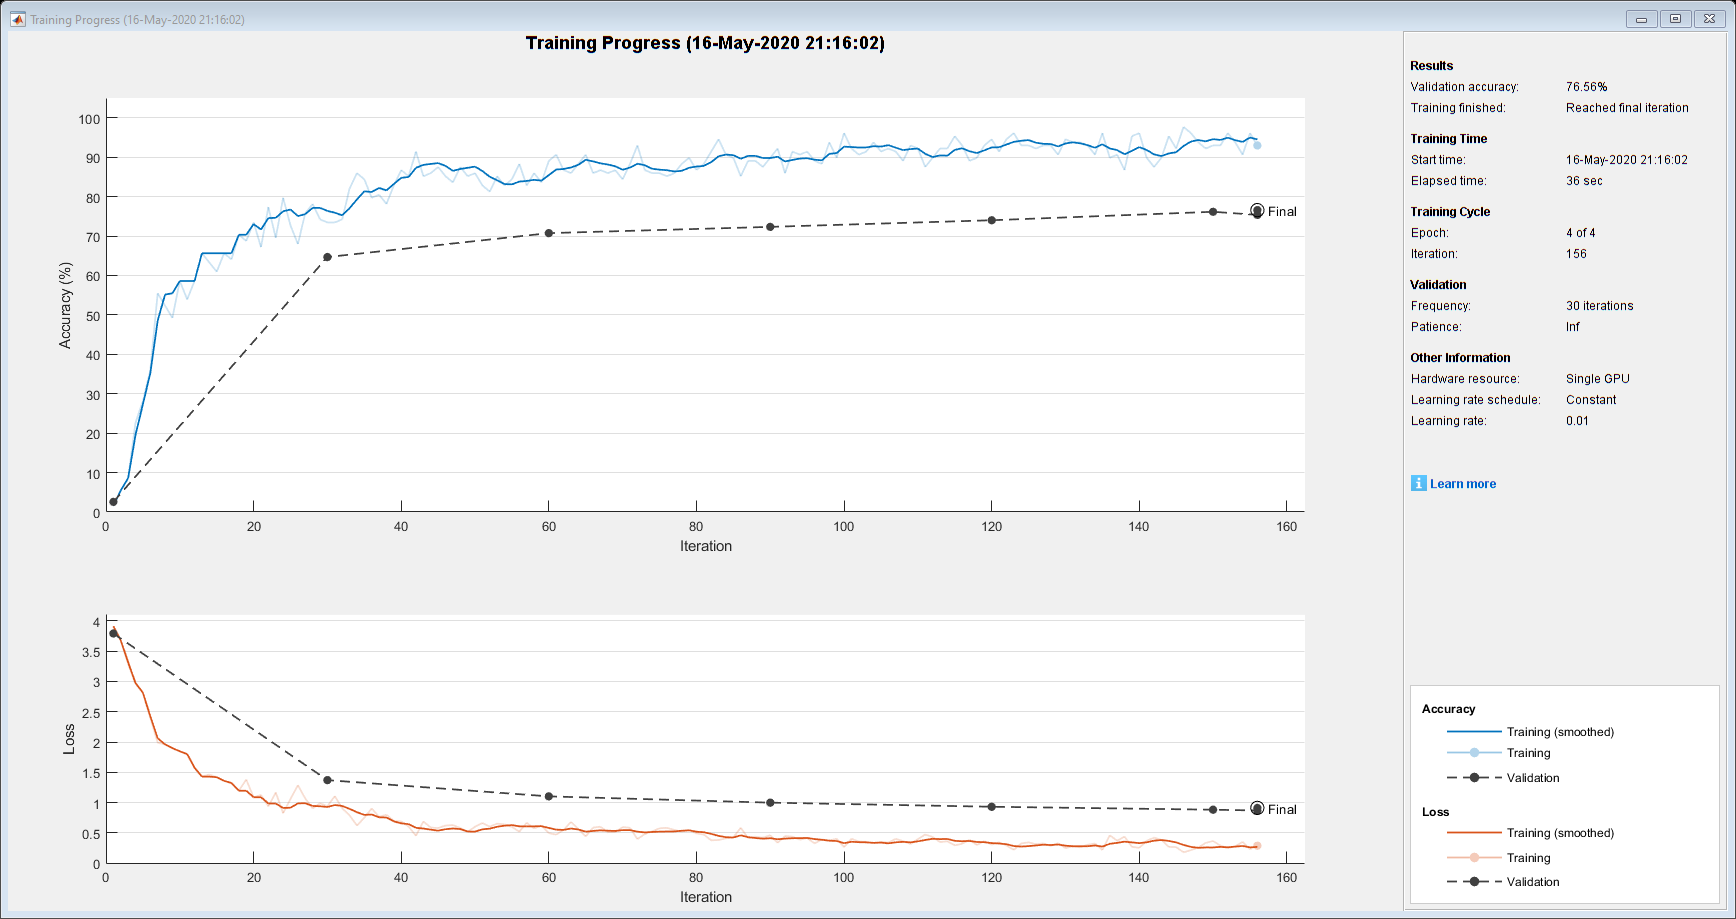

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        1.56% |        2.57% |       3.9126 |       3.7928 |          0.0100 |
|       1 |          30 |       00:00:09 |       73.44% |       64.66% |       0.9403 |       1.3711 |          0.0100 |
|       2 |          50 |       00:00:11 |       85.94% |              |       0.6012 |              |          0.0100 |
|       2 |          60 |       00:00:15 |       89.06% |       70.73% |       0.4971 |   

xarxa = trainNetwork(trainData, layers, options);

labels = categories(trainData.UnderlyingDatastore.Labels);

save xarxa;